clear all
close all
path = 'InvestmentReplica.mat';
load(path)

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

% Synthetic target weights
wMXWO = 0.2; 
wMXWD = 0.2;
wLEGATRUU = 0.6;
%Primi due simili

% Building the target
y = wMXWD*price2ret(MXWD) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

%rw 104 156 208 260 + alpha 0.05 0.5 0.95
rollingWindows = [104, 156, 208, 260];
alphas = [0.05, 0.5, 0.95];
% create the variables as cellmatrices to store the results
bEnet2s = cell(length(rollingWindows), length(alphas));
rEnet2s = cell(length(rollingWindows), length(alphas));
GrossExposures = cell(length(rollingWindows), length(alphas));

warning('off','all'); % avoid annoying warnings during the loops
for i = 1:length(rollingWindows)
    for j = 1:length(alphas)

        %create the variables for the current combination
        k = 1;
        rollingWindow = rollingWindows(i);
        alpha = alphas(j);
        b = []; bEnet2 = []; rEnet2 = []; GrossExposure = [];
        endSample = 0;

        % do the usual while loop but using k instead of i
        while endSample <= (length(X)-2)
            startSample = k; endSample = k+rollingWindow-1;
            % compute the lasso regression
            [b,fitinfo] = lasso(X(startSample:endSample,:),y(startSample:endSample),'Alpha',alpha,'CV',5, 'Intercept',false);
            % lambda half-way between MinMSE and 1SE away from MinMSE
            lam = round((fitinfo.Index1SE + fitinfo.IndexMinMSE)/2);
            b = b(:,lam);
            GrossExposure = [GrossExposure; sum(abs(b))];
            bEnet2 = [bEnet2; b'];
            r = X(endSample + 1,:)*b;
            rEnet2 = [rEnet2; r];
            k = k+1;
        end

        % save the data into the variables by adding a cell (this is due to the
        % fact that the arrays are all of differings legths)
        % we don't save b since we already store the important bits in bEnet2
        bEnet2s{i,j} = bEnet2;
        rEnet2s{i,j} = rEnet2;
        GrossExposures{i,j} = GrossExposure;
    end
end

warning('on','all'); % warnings on again

**Financial statistics**

TEV -> Per confronto 

% create matrices with same dimensions as rEnet2s
TEV = zeros(size(rEnet2s));
meanTRTarget = zeros(size(rEnet2s)); meanTRClone = zeros(size(rEnet2s)); meanER = zeros(size(rEnet2s));
IR = zeros(size(rEnet2s));
meanTurnover = zeros(size(rEnet2s)); meanTradingCosts = zeros(size(rEnet2s));
NetER = zeros(size(rEnet2s)); NetTR = zeros(size(rEnet2s)); NetIR = zeros(size(rEnet2s));

for i = 1:length(rollingWindows)
    % get the rollingwindow
    rollingWindow = rollingWindows(i);
    for j = 1:length(alphas)
        rEnet2 = rEnet2s{i,j};
        bEnet2 = bEnet2s{i,j};
        % tracking error and tracking error volatility
        TE = rEnet2 - y(rollingWindow + 1: end); 
        TEV(i,j) = std(TE)*sqrt(52);
        % mean excess return
        logRClone = diff(log(ret2price(rEnet2)));
        logRTarget = diff(log(ret2price(y(rollingWindow + 1: end))));
        logTE =  logRClone - logRTarget;
        meanTRTarget(i,j) = exp(mean(logRTarget)*52) - 1;
        meanTRClone(i,j) = exp(mean(logRClone)*52) - 1;
        meanER(i,j) = exp(mean(logTE)*52) - 1;
        % Information Ratio
        IR(i,j) = meanER(i,j)/TEV(i,j);
        % turnover
        Turnover = calcTurnover(bEnet2); % weekly turnover
        meanTurnover(i,j) = mean(Turnover)*52; % average annual turnover
        tradingCosts = 0.0004; % transaction costs (hp: buyCosts=sellCost)
        meanTradingCosts(i,j) = meanTurnover(i,j)*tradingCosts;
        % Net ER
        NetTR(i,j) = meanTRClone(i,j) - meanTradingCosts(i,j); % transaction costs (hp: buyCosts=sellCost)
        NetER(i,j) = meanER(i,j) - meanTradingCosts(i,j);
        NetIR(i,j) = NetER(i,j)/TEV(i,j);
    end
end
disp(TEV)

    0.0345    0.0345    0.0343
    0.0333    0.0333    0.0335
    0.0323    0.0319    0.0318
    0.0326    0.0320    0.0321



disp(meanTRTarget)

    0.0468    0.0468    0.0468
    0.0462    0.0462    0.0462
    0.0504    0.0504    0.0504
    0.0472    0.0472    0.0472



disp(meanTRClone)

    0.0462    0.0462    0.0466
    0.0463    0.0448    0.0432
    0.0491    0.0495    0.0471
    0.0452    0.0435    0.0432



disp(meanER)

   -0.0005   -0.0005   -0.0001
    0.0002   -0.0013   -0.0029
   -0.0012   -0.0009   -0.0032
   -0.0019   -0.0035   -0.0039



disp(IR)

   -0.0149   -0.0155   -0.0036
    0.0046   -0.0388   -0.0855
   -0.0386   -0.0274   -0.0997
   -0.0587   -0.1092   -0.1203



disp(NetER)

   -0.0024   -0.0054   -0.0060
   -0.0016   -0.0052   -0.0081
   -0.0029   -0.0043   -0.0078
   -0.0037   -0.0067   -0.0079



Gross

In generale, un buon risultato in un portafoglio di replica dovrebbe essere caratterizzato da un ER positivo, una volatilità limitata e una bassa correlazione con il benchmark di riferimento. Un portafoglio che ottiene un ER positivo ma con una volatilità elevata potrebbe essere più rischioso di quanto sia accettabile, mentre un portafoglio con un ER negativo ma una bassa volatilità potrebbe essere considerato accettabile se offre una buona protezione dal rischio.

Quando l'ER del portafoglio di replica è più alto del target, significa che il portafoglio di replica ha generato un rendimento superiore rispetto all'indice di riferimento, ovvero il portafoglio target. In altre parole, il portafoglio di replica ha aggiunto valore rispetto all'indice di riferimento.

Ci possono essere diverse ragioni per cui ciò accade. Ad esempio, il gestore del portafoglio di replica potrebbe aver selezionato titoli o strategie di investimento che hanno reso meglio rispetto a quelli del portafoglio target. 

Tuttavia, è importante valutare anche altri fattori oltre all'ER per determinare se il risultato del portafoglio di replica è effettivamente positivo. Ad esempio, è importante considerare la volatilità del portafoglio, la diversificazione e il rischio complessivo del portafoglio.

% get the best combinations by getting the max Net ER
maxNetER = max(max(NetER))

maxNetER = -0.0016

[Mi, Mj] = find(NetER == maxNetER);
rollingWindow = rollingWindows(Mi);
rEnet2 = rEnet2s{Mi,Mj};
GrossExposure = GrossExposures{Mi,Mj};

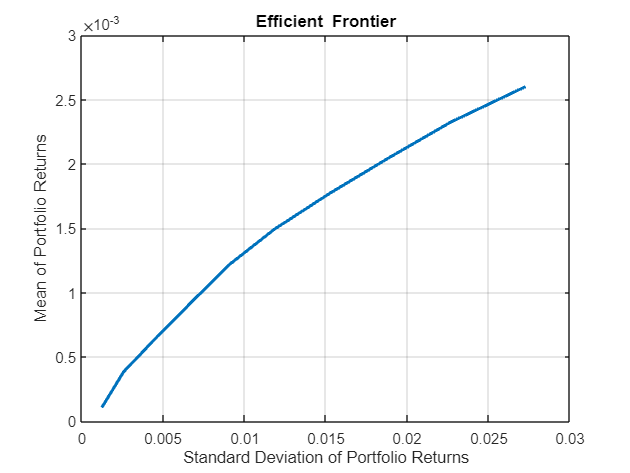

m = mean(X);
c = cov(X);
assetNames = ["RX1", "TY1", "GC1", "CO1", "ES1", "VG1", "NQ1","LLL1","TP1","DU1","TU2"];
%assetNames = cellstr(assetNames);
p = Portfolio('AssetList', assetNames(1:11));
p = Portfolio(p, 'assetmean', m, 'assetcovar', c);
p = Portfolio(p, 'lowerbudget', 1, 'upperbudget', 1);
p = Portfolio(p, 'lowerbound', 0);
 
plotFrontier(p);

pwgt = estimateFrontier(p);
pnames = sprintf('PortafoglioMeanVar');
Weights = dataset([{pwgt(:,1)},pnames],'obsnames',p.AssetList);
disp(Weights);

            PortafoglioMeanVar
    RX1     0.00050345        
    TY1        0.60187        
    GC1      0.0042875        
    CO1              0        
    ES1       0.010445        
    VG1              0        
    NQ1              0        
    LLL1     0.0076303        
    TP1        0.36831        
    DU1              0        
    TU2      0.0069548        



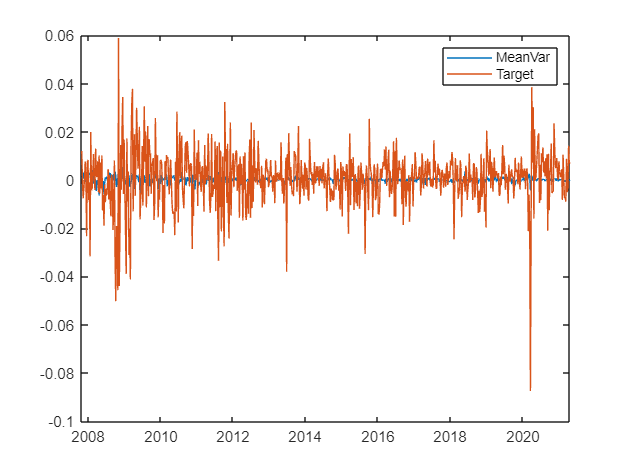

wVar = pwgt(:,1);
figure
plot(Date(2:end), X*wVar)
hold on
plot(Date(2:end), y)
legend('MeanVar','Target')
hold off